# Generation of a chemoinformatic data base 

#### Author: German Preciat, Analytical BioSciences and Metabolomics, Leiden University.

## INTRODUCTION

The molecular structure of a metabolite in a COBRA model can be represented in various formats such as SMILES InChIs and InChIkeys (See Figure 1), as well as identifiers from various databases such as the Virtual Metabolic Human database${\;}^1$ (**VMH**), the Human Metabolome Database${\;}^2$ (**HMDB**), **PubChem** database${\;}^3$, the Kyoto Encyclopedia of Genes and Genomes${\;}^4$ (**KEEG**), and the Chemical Entities of Biological Interest${\;}^5$ (**ChEBI**). 

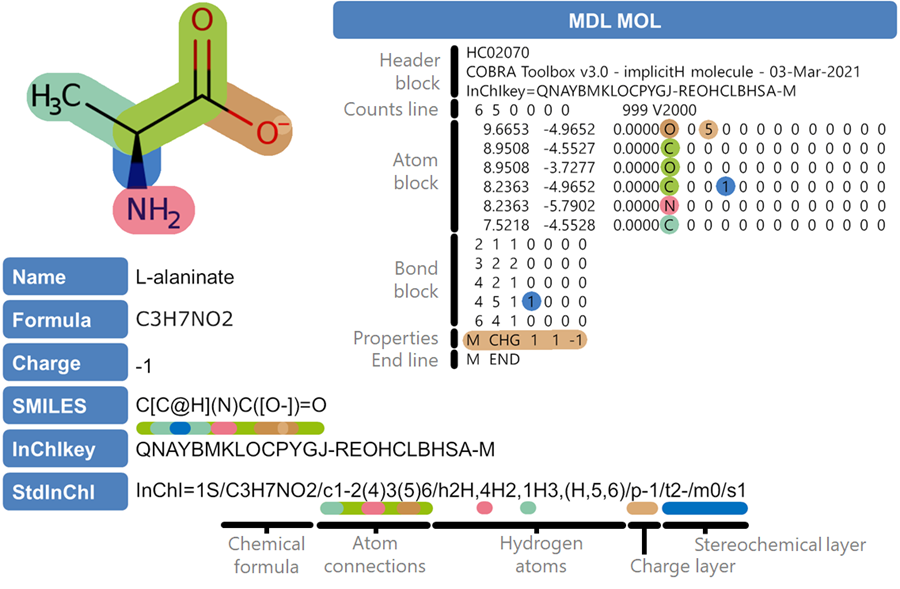

Figure 1. Different chemoinformatic formats

The function generateChemicalDatabase creates a chemoinformatic database using data from a COBRA model (Figure 2). It makes use of a variety of external software, including openBabel${\;}^6$, MarvinSuite${\;}^7$, and JAVA. generateChemicalDatabase works even if some of these programs are not installed, but for the best results, all of them should be.

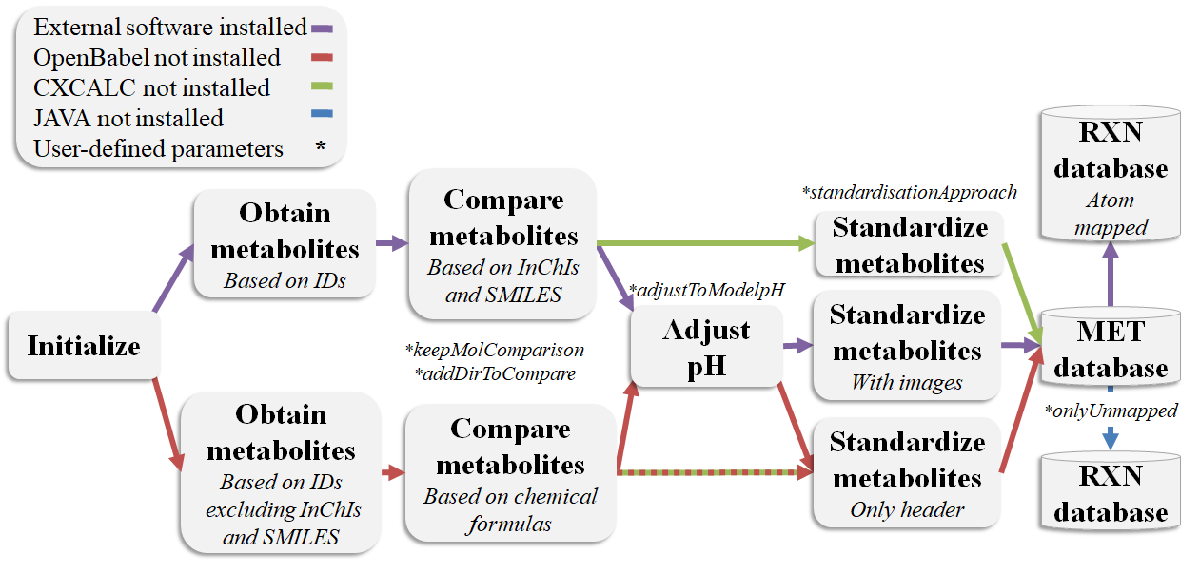

Figure 2. Depending on the system configuration and the user-defined parameters, the pipeline can take various paths.

The function compares the molecular structure information from various sources for each metabolite, and the molecular structure from the source with the highest score is considered correct. The disimilarity comparison is performed by calculating the euclidean distances of all molecular structures obtained. The following criteria are used to assign the score:

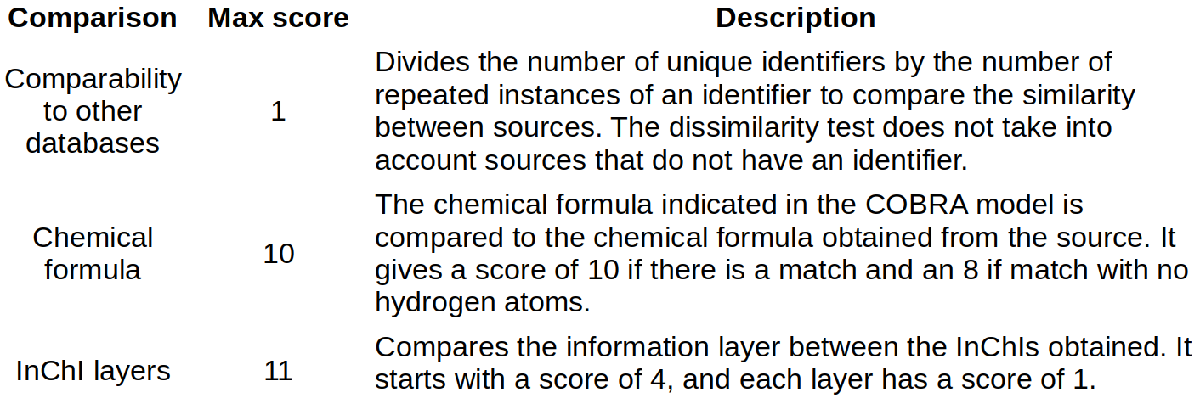

The goal of the comparison is to obtain a larger number of atomically balanced metabolic reactions. The Reaction Decoder Tool algorithm${\;}^8$ (**RDT**) is used to obtain the atom mappings of each metabolic reaction. Finally, the atom mapping data is used to calculate the number of bonds formed or broken in a metabolic reaction, as well as the energy required to break the bond. The information gathered is incorporated into the COBRA model.

We will obtain chemoinformatic data on the Ecoli core model in this tutorial. The identifiers will be added using the  `addMetInfoInCBmodel` function.

## Generate chemoinformatic database

Clean up the workspace and configure the user directory.

clear
if ispc
    userDir = winqueryreg('HKEY_CURRENT_USER',...
        ['Software\Microsoft\Windows\CurrentVersion\' ...
         'Explorer\Shell Folders'],'Personal');
else
    userDir = char(java.lang.System.getProperty('user.home'));
end

Load the ecoli core model.

load ecoli_core_model.mat
model.mets = regexprep(model.mets, '\-', '\_');

Add chemoinformatic information from an external file to the ecoli core model, such as SMILES, InChIs, or different database identifiers.

dataFile = which('chemoinformaticDatabaseTutorial.mlx')
inputData = regexprep(dataFile, 'chemoinformaticDatabaseTutorial.mlx', 'metaboliteIds.xlsx');
replace = false;

dataFile = '/Users/gpreciat/work/code/cobratoolbox/tutorials/dataIntegration/chemoinformaticDatabase/chemoinformaticDatabaseTutorial.mlx'

[model, hasEffect] = addMetInfoInCBmodel(model, inputData, replace);

The user-defined parameters in the function `generateChemicalDatabase` will activate various processes. Each parameter is described in detail below:

- **outputDir**: The path to the directory containing the RXN files with atom mappings (default: current directory)

- **printlevel**: Verbose level 

- **standardisationApproach**: String containing the type of standardisation for the molecules (default: 'explicitH' if openBabel${\;}^6$ is installed, otherwise default: 'basic'):

-     explicitH: Normal chemical graphs; 

-     implicitH: Hydrogen suppressed chemical graph; 

-     neutral: Chemical graphs with protonated molecules; 

-     basic: Update the header.  

- **keepMolComparison**: Logic value for comparing MDL MOL files from various sources (default: FALSE) 

- **onlyUnmapped**: Logic value to select create only unmapped MDL RXN files (default: FALSE). 

- **adjustToModelpH**: Logic value used to determine whether a molecule's pH must be adjusted in accordance with the COBRA model. (default: TRUE, requires MarvinSuite${\;}^7$). 

- **addDirsToCompare**: Cell(s) with the path to directory to an existing database (default: empty).

- **dirNames**: Cell(s) with the name of the directory(ies) (default: empty).

- **debug**: Logical value used to determine whether or not the results of different points in the function will be saved for debugging (default: empty).

options.outputDir = [userDir '/work/code/ctf/databases/ecoliDB'];
options.printlevel = 1;
options.debug = true;
options.standardisationApproach = 'explicitH';
options.adjustToModelpH = true;
options.keepMolComparison = true;
options.dirsToCompare = {'~/work/code/ctf/mets/molFiles'};
options.onlyUnmapped = false;
options.dirNames = {'VMH'};

Use the function generateChemicalDatabase

--------------------------------------------------------------
CHEMICAL DATABASE
--------------------------------------------------------------
 
Generating a chemical database with the following options:
 
                  outputDir: '/Users/gpreciat/work/code/ctf/databases/ecoliDB'
                 printlevel: 1
                      debug: 1
    standardisationApproach: 'explicitH'
            adjustToModelpH: 1
          keepMolComparison: 1
              dirsToCompare: {'~/work/code/ctf/mets/molFiles/'}
               onlyUnmapped: 0
                   dirNames: {'VMH'}

--------------------------------------------------------------
Obtaining MOL files from chemical databases ...

inchi:


molCollectionReport = struct with fields:
              noOfMets: 54
       noOfMetsWithMol: 50
    noOfMetsWithoutMol: 4
              coverage: 92.5926


smiles:


molCollectionReport = struct with fields:
              noOfMets: 54
       noOfMetsWithMol: 50
    noOfMetsWithoutMol: 4
              coverage: 92.5926


KEGG:


molCollectionReport = struct with fields:
              noOfMets: 54
       noOfMetsWithMol: 49
    noOfMetsWithoutMol: 5
              coverage: 90.7407


HMDB:


molCollectionReport = struct with fields:
              noOfMets: 54
       noOfMetsWithMol: 51
    noOfMetsWithoutMol: 3
              coverage: 94.4444


PubChem:


molCollectionReport = struct with fields:
              noOfMets: 54
       noOfMetsWithMol: 50
    noOfMetsWithoutMol: 4
              coverage: 92.5926


CHEBI:


molCollectionReport = struct with fields:
              noOfMets: 54
       noOfMetsWithMol: 48
    noOfMetsWithoutMol: 6
              coverage: 88.8889


Comparing information from sources ...
  52×8 table

      mets                sourceWithHighestScore                                     metNames                              metFormulas        sourceFormula      layersInChI    socre                                                                                                                                                                       idUsed                                                                                                                                                                  
    ________    __________________________________________    _______________________________________________________    ________________    _______________

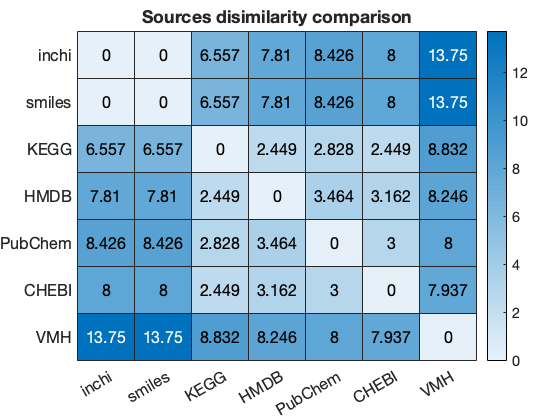

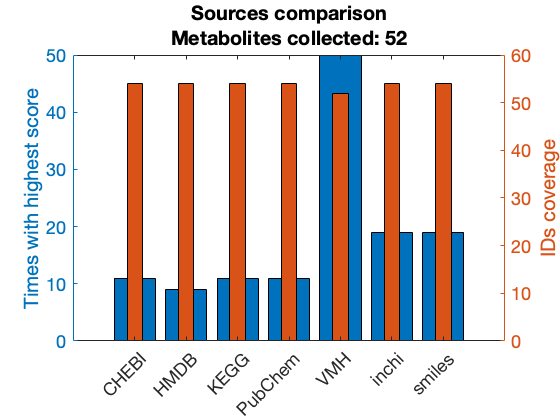

Adjusting pH based on the model's chemical formula ...
 
adjustedpH:
  52×13 table

      mets                sourceWithHighestScore                                     metNames                              metFormulas        sourceFormula      layersInChI    socre                                                                                                                                                                       idUsed                                                                                                                                                                      needAdjustmentBool    notPossible2AdjustBool    differentFormula    loopError    pHRangePassed
    ______

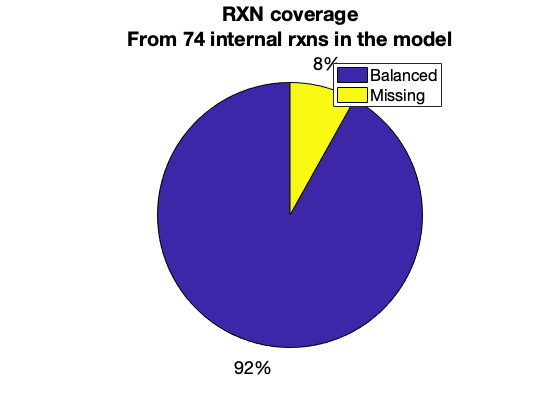

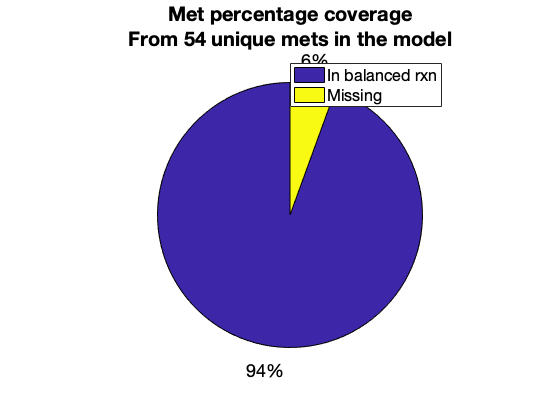

Obtaining RInChIes and reaction SMILES ...
Found biomass reaction: Biomass_Ecoli_core_N(w/GAM)-Nmet2
ATP maintenance reaction is not considered an exchange reaction by default. It should be mass balanced:
ATPM	atp[c] + h2o[c] 	->	adp[c] + h[c] + pi[c] 


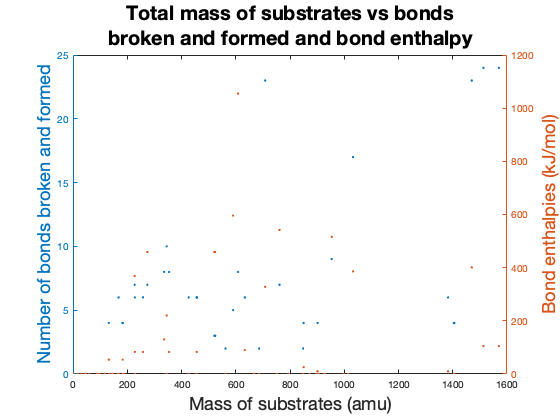

  95×4 table

                   rxns                                                    rxnNames                                    bondsBF    bondsE
    ___________________________________    ________________________________________________________________________    _______    ______

    'ACALD'                                'acetaldehyde dehydrogenase (acetylating)'                                     23        401 
    'ACALDt'                               'acetaldehyde reversible transport'                                             0          0 
    'ACKr'                                 'acetate kinase'                                                                2          0 
    'ACONTa'                               'aconitase (half-reaction A, Citrate hydro-lyase)'         

info = generateChemicalDatabase(model, options);

## Bibliography

- Noronha et al., "The Virtual Metabolic Human database: integrating human and gut microbiome metabolism with nutrition and disease", *Nucleic acids research* **(2018).**

- Wishart et al., "HMDB 4.0 — The Human Metabolome Database for 2018*".* *Nucleic acids research* **(2018).**

- Sunghwan et al. “PubChem in 2021: new data content and improved web interfaces.” *Nucleic acids research* **(2021).**

- Kanehisa, and Goto. "KEGG: Kyoto Encyclopedia of Genes and Genomes". *Nucleic acids research* **(2000).**

- Hastings et al,. "ChEBI in 2016: Improved services and an expanding collection of metabolites". *Nucleic acids research* **(2016).**

- O'Boyle et al,. "Open Babel: An open chemical toolbox." *Journal of Cheminformatics* **(2011).**

- "Marvin was used for drawing, displaying and characterizing chemical structures, substructures and reactions, ChemAxon ([http://www.chemaxon.com](http://www.chemaxon.com/))"

- Rahman et al,. "Reaction Decoder Tool (RDT): Extracting Features from Chemical Reactions", Bioinformatics **(2016).**